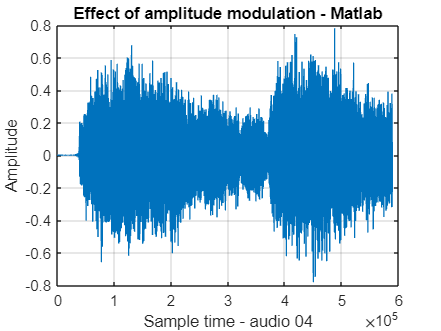

faudio = audioread("audiofiles\sample04.wav");
faudio2 = audioread("build\wav_effects_out_am.wav");%amplitude
faudio3 = audioread("build\wav_effects_out_singleEcho.wav");
faudio4 = audioread("build\wav_effects_out_multiEcho.wav");
faudio5 = audioread("build\wav_quant_out_round.wav");
faudio6 = audioread("build\wav_quant_out_midriser.wav");
faudio7 = audioread("build\wav_quant_out_midtread.wav");
faudio8 = audioread("build\wav_quant_out_shift.wav");

figure(1)
plot(modulate(faudio(:,1),500,44100));
title("Effect of amplitude modulation - Matlab");
xlabel("Sample time - audio 04");
ylabel("Amplitude");
grid on

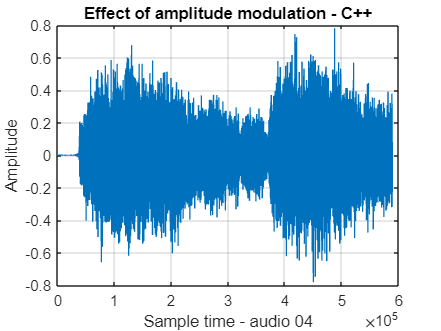

figure(2)
plot(faudio2(:,1));
title("Effect of amplitude modulation - C++");
xlabel("Sample time - audio 04");
ylabel("Amplitude");
grid on

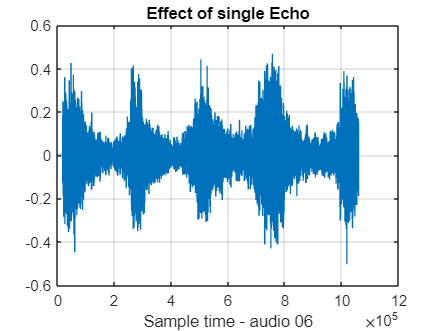

figure(3)
plot(faudio3(:,1));
title("Effect of single Echo");
xlabel("Sample time - audio 06");
grid on

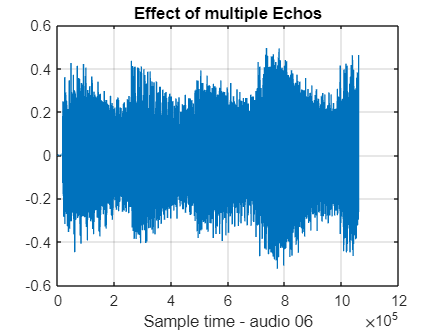

figure(4)
plot(faudio4(:,1));
title("Effect of multiple Echos");
xlabel("Sample time - audio 06");
grid on

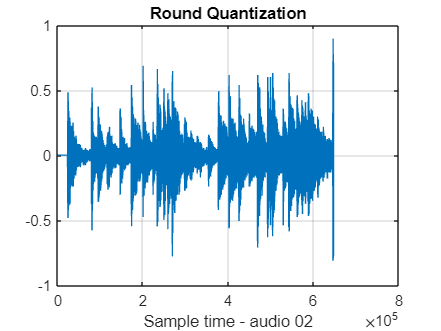

figure(5)
plot(faudio5(:,1));
title("Round Quantization");
xlabel("Sample time - audio 02");
grid on

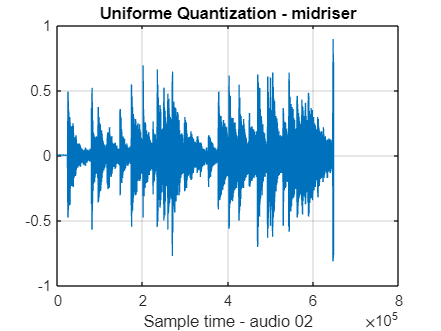

figure(6)
plot(faudio6(:,1));
title("Uniforme Quantization - midriser");
xlabel("Sample time - audio 02");
grid on

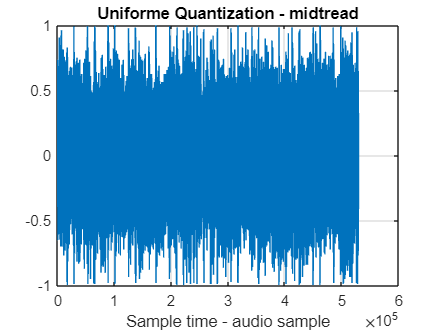

figure(7)
plot(faudio7(:,1));
title("Uniforme Quantization - midtread");
xlabel("Sample time - audio sample");
grid on

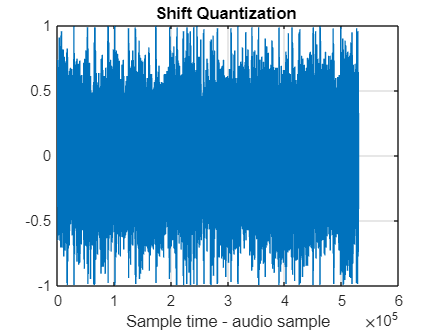

figure(8)
plot(faudio8(:,1));
title("Shift Quantization ");
xlabel("Sample time - audio sample");
grid on

%{
figure(4)
subplot(3,1,1);
[x,fs]=audioread('build\wav_effects_out_singleEcho.wav');
info = audioinfo( 'build\wav_effects_out_singleEcho.wav');
N=length(x);
T=2.9520;
t=linspace(0,T,N);
plot(t,x);
xlabel('Sample time(s)')
ylabel('Amplitute')
title('Effect of single Echo')
y=abs(fftshift(fft(x)));
F=linspace(-fs/2,fs/2,N);
subplot(3,1,2);
plot(F,y);
%}
